# Locally Weighted Scatterplot Smoothing

A program which is developed based on lowess approach for smoothing rate-normalized pressure (RNP) data.

Author: Munthe, Felix A.

Created on Monday, 30 October 2023

## Import Data

### True RNP Data

clear; clc; clf;
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t", "RNP"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
true_RNP = readtable("C:\Users\ASUS\Documents\Kuliah\2. Master's Texas A&M University\Publications\Conference Paper\Smoothing Paper\Smoothing Simulator\true_RNP.txt", opts)

true_RNP = 1150×2 table
       t          RNP    
    _______    __________

       0.25    1.3616e+06
    0.33041    1.9565e+06
     0.4862    2.6089e+06
    0.79777    3.4782e+06
     1.4209    4.6953e+06
     2.6672    6.4232e+06
     5.0773    8.8236e+06
     9.8974    1.2258e+07
     19.198    1.7054e+07
     35.645    2.3347e+07
      66.06    3.1893e+07
     124.99    4.3906e+07
     188.99    5.4925e+07
     252.99    6.4572e+07
     316.99    7.3193e+07
     380.99     8.103e+07


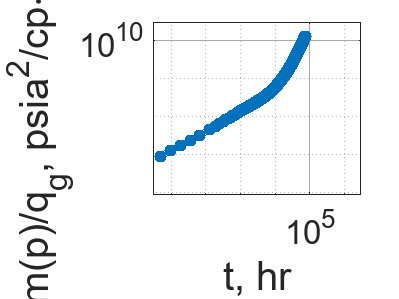


% Plot
loglog(true_RNP.t, true_RNP.RNP, ".", "MarkerSize", 25,"Color", "#0072BD");
% title("True RNP Data", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold off;

### Noisy RNP Data Set 191

opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t", "RNP"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
noisy_RNP_191 = readtable("C:\Users\ASUS\Documents\Kuliah\2. Master's Texas A&M University\Publications\Conference Paper\Smoothing Paper\Smoothing Simulator\Noisy RNP Model\All\50%\noisy_data_1.txt", opts)

noisy_RNP_191 = 1150×2 table
       t          RNP    
    _______    __________

       0.25    6.0175e+07
    0.33041    6.7296e+07
     0.4862    1.8373e+08
    0.79777    1.2799e+07
     1.4209    4.6953e+06
     2.6672    6.4232e+06
     5.0773    8.8236e+06
     9.8974    1.2258e+07
     19.198    1.8281e+08
     35.645    2.3347e+07
      66.06    3.1893e+07
     124.99    4.3906e+07
     188.99    2.9716e+08
     252.99    6.4572e+07
     316.99    7.3193e+07
     380.99     8.103e+07


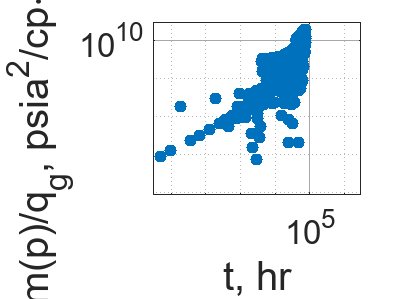


% Plot
loglog(noisy_RNP_191.t, noisy_RNP_191.RNP, ".", "MarkerSize", 25,"Color", "#0072BD");
% title("Noisy RNP Data Set 191", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold off;

## Smoothing

### Noisy RNP Data 191

logRNP_191 = log(noisy_RNP_191.RNP);

#### Window: 3

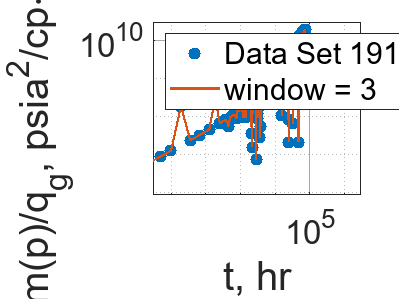

% Plot
loglog(noisy_RNP_191.t, noisy_RNP_191.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 191");
% title("Noisy RNP Data Set 191", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_191_31 = smooth(logRNP_191, 3, "lowess");
smoothedRNP_191_31 = exp(smoothedLogRNP_191_31);
residual_191_31 = (true_RNP.RNP - smoothedRNP_191_31) ./ (0.3413 .* true_RNP.RNP);
sse_191_31 = sum(residual_191_31 .^ 2);
loglog(noisy_RNP_191.t, smoothedRNP_191_31, "-", "LineWidth", 1.3, "DisplayName", "window = 3");
legend("Location", "northwest");
hold off;

### Window: 5

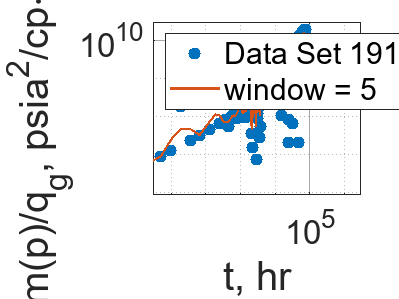

% Plot
loglog(noisy_RNP_191.t, noisy_RNP_191.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 191");
% title("Noisy RNP Data Set 191", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_191_51 = smooth(logRNP_191, 5, "lowess");
smoothedRNP_191_51 = exp(smoothedLogRNP_191_51);
residual_191_51 = (true_RNP.RNP - smoothedRNP_191_51) ./ (0.3413 .* true_RNP.RNP);
sse_191_51 = sum(residual_191_51 .^ 2);
loglog(noisy_RNP_191.t, smoothedRNP_191_51, "-", "LineWidth", 1.3, "DisplayName", "window = 5");
legend("Location", "northwest");
hold off;

#### Window: 7

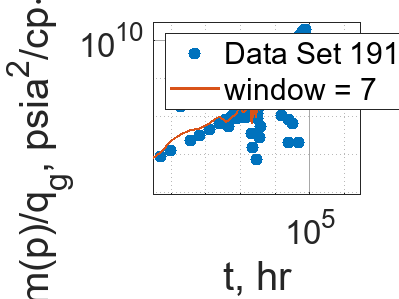

% Plot
loglog(noisy_RNP_191.t, noisy_RNP_191.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 191");
% title("Noisy RNP Data Set 191", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_191_71 = smooth(logRNP_191, 7, "lowess");
smoothedRNP_191_71 = exp(smoothedLogRNP_191_71);
residual_191_71 = (true_RNP.RNP - smoothedRNP_191_71) ./ (0.3413 .* true_RNP.RNP);
sse_191_71 = sum(residual_191_71 .^ 2);
loglog(noisy_RNP_191.t, smoothedRNP_191_71, "-", "LineWidth", 1.3, "DisplayName", "window = 7");
legend("Location", "northwest");
hold off;

#### Window: 9

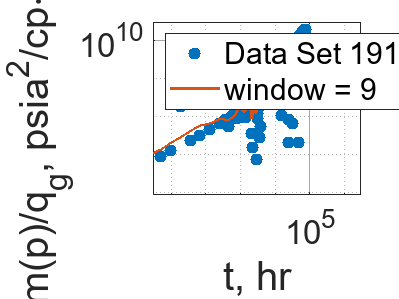

% Plot
loglog(noisy_RNP_191.t, noisy_RNP_191.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 191");
% title("Noisy RNP Data Set 191", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_191_91 = smooth(logRNP_191, 9, "lowess");
smoothedRNP_191_91 = exp(smoothedLogRNP_191_91);
residual_191_91 = (true_RNP.RNP - smoothedRNP_191_91) ./ (0.3413 .* true_RNP.RNP);
sse_191_91 = sum(residual_191_91 .^ 2);
loglog(noisy_RNP_191.t, smoothedRNP_191_91, "-", "LineWidth", 1.3, "DisplayName", "window = 9");
legend("Location", "northwest");
hold off;

#### Window: 11

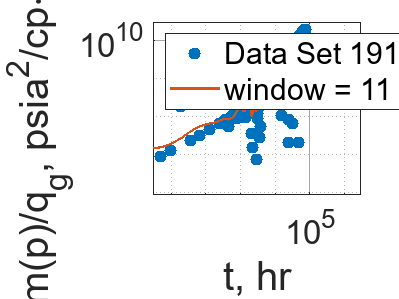

% Plot
loglog(noisy_RNP_191.t, noisy_RNP_191.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 191");
% title("Noisy RNP Data Set 191", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_191_111 = smooth(logRNP_191, 11, "lowess");
smoothedRNP_191_111 = exp(smoothedLogRNP_191_111);
residual_191_111 = (true_RNP.RNP - smoothedRNP_191_111) ./ (0.3413 .* true_RNP.RNP);
sse_191_111 = sum(residual_191_111 .^ 2);
loglog(noisy_RNP_191.t, smoothedRNP_191_111, "-", "LineWidth", 1.3, "DisplayName", "window = 11");
legend("Location", "northwest");
hold off;

#### Window: 13

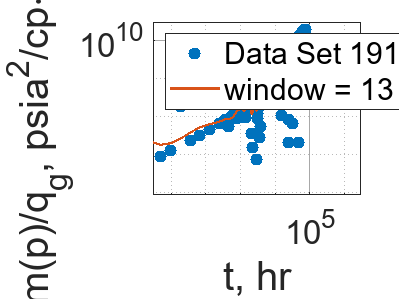

% Plot
loglog(noisy_RNP_191.t, noisy_RNP_191.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 191");
% title("Noisy RNP Data Set 191", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_191_131 = smooth(logRNP_191, 13, "lowess");
smoothedRNP_191_131 = exp(smoothedLogRNP_191_131);
residual_191_131 = (true_RNP.RNP - smoothedRNP_191_131) ./ (0.3413 .* true_RNP.RNP);
sse_191_131 = sum(residual_191_131 .^ 2);
loglog(noisy_RNP_191.t, smoothedRNP_191_131, "-", "LineWidth", 1.3, "DisplayName", "window = 13");
legend("Location", "northwest");
hold off;

#### Window: 15

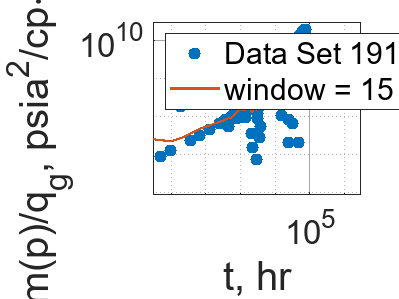

% Plot
loglog(noisy_RNP_191.t, noisy_RNP_191.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 191");
% title("Noisy RNP Data Set 191", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_191_151 = smooth(logRNP_191, 15, "lowess");
smoothedRNP_191_151 = exp(smoothedLogRNP_191_151);
residual_191_151 = (true_RNP.RNP - smoothedRNP_191_151) ./ (0.3413 .* true_RNP.RNP);
sse_191_151 = sum(residual_191_151 .^ 2);
loglog(noisy_RNP_191.t, smoothedRNP_191_151, "-", "LineWidth", 1.3, "DisplayName", "window = 15");
legend("Location", "northwest");
hold off;

#### Window: 17

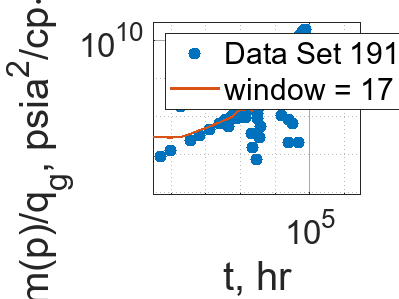

% Plot
loglog(noisy_RNP_191.t, noisy_RNP_191.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 191");
% title("Noisy RNP Data Set 191", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_191_171 = smooth(logRNP_191, 17, "lowess");
smoothedRNP_191_171 = exp(smoothedLogRNP_191_171);
residual_191_171 = (true_RNP.RNP - smoothedRNP_191_171) ./ (0.3413 .* true_RNP.RNP);
sse_191_171 = sum(residual_191_171 .^ 2);
loglog(noisy_RNP_191.t, smoothedRNP_191_171, "-", "LineWidth", 1.3, "DisplayName", "window = 17");
legend("Location", "northwest");
hold off;

#### Window: 19

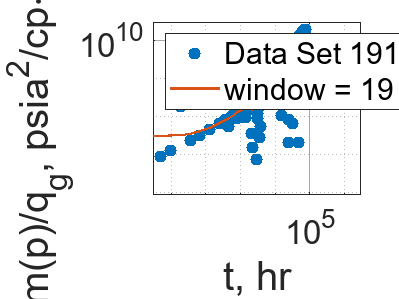

% Plot
loglog(noisy_RNP_191.t, noisy_RNP_191.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 191");
% title("Noisy RNP Data Set 191", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_191_191 = smooth(logRNP_191, 19, "lowess");
smoothedRNP_191_191 = exp(smoothedLogRNP_191_191);
residual_191_191 = (true_RNP.RNP - smoothedRNP_191_191) ./ (0.3413 .* true_RNP.RNP);
sse_191_191 = sum(residual_191_191 .^ 2);
loglog(noisy_RNP_191.t, smoothedRNP_191_191, "-", "LineWidth", 1.3, "DisplayName", "window = 19");
legend("Location", "northwest");
hold off;